
temp.curr_timesteps_array = across_experiment_results{1, 1}.timesteps_array;  
temp.curr_active_processing = across_experiment_results{1, 1}.active_processing;

temp.currWindowRegion = [2647 2657];

temp.currDataSpikeTimes = temp.curr_active_processing.spikes.time(plot_outputs.filter_active_units);
temp.currData = temp.curr_active_processing.spikes.ISIs(plot_outputs.filter_active_units);

temp.currDataFFT = cellfun(@fft, temp.currData, 'UniformOutput', false);


% Get cell array of indicies that fall within the window times
for i = 1:length(temp.currDataSpikeTimes)

    temp.currWindowSpikeIncludeIndicies{i} = ((temp.currDataSpikeTimes{i} >= temp.currWindowRegion(1)) & (temp.currDataSpikeTimes{i} <= temp.currWindowRegion(2)));
%     temp.curr_active_processing.spikes.time(plot_outputs.filter_active_units)
    temp.currWindowSpikeTimes{i} = temp.currDataSpikeTimes{i}(temp.currWindowSpikeIncludeIndicies{i});
    temp.currWindowSpikeData{i} = temp.currData{i}(temp.currWindowSpikeIncludeIndicies{i});

end

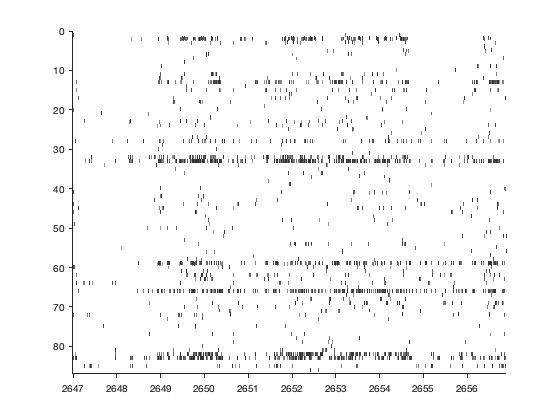

figure;
[~, ~, temp.plotHandle] = plotSpikeRaster(temp.currWindowSpikeTimes,'PlotType','vertline');

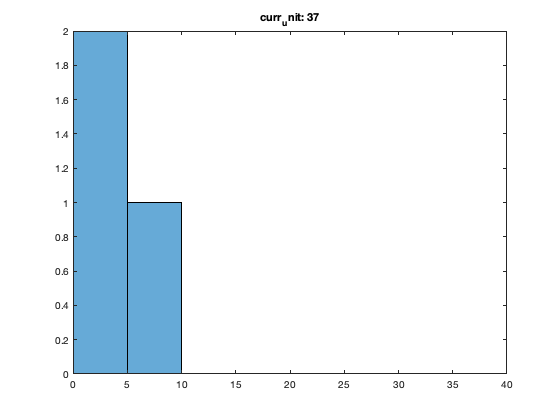

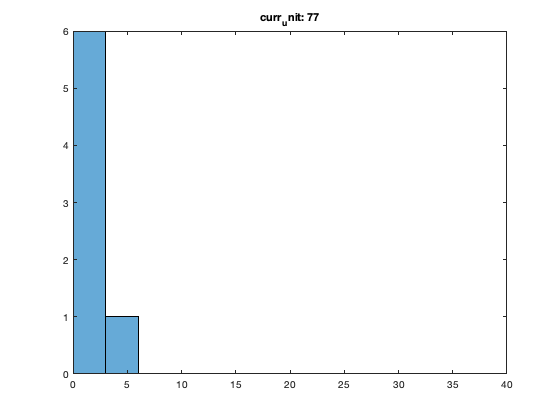

% temp.units_of_interest = [51, 108];
temp.units_of_interest = [37, 77];

for i = 1:length(temp.units_of_interest)
    figure;
    temp.curr_unit_of_interest = temp.units_of_interest(i);
    
%     plot(abs(temp.currDataFFT{temp.curr_unit_of_interest}));
    [counts, edges] = histcounts(temp.currData{temp.curr_unit_of_interest}(temp.currWindowSpikeIncludeIndicies{temp.curr_unit_of_interest}));
    histogram('BinEdges',edges,'BinCounts',counts)
    title(sprintf('curr_unit: %d', temp.curr_unit_of_interest));
    xlim([0 40]);
end

temp.included_unit_indicies = [2, 13, 31, 32];
[is_pair_included, original_pair_index] = fnFilterPairsWithCriteria(across_experiment_results{1}.general_results, temp.included_unit_indicies)

is_pair_included = 7875×4 logical array
   1   0   0   0
   1   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


original_pair_index =            1          12          30          31
           2         136         154         155
         126         259         277         278
         127         381         399         400
         128         502         520         521
         129         622         640         641
         130         741         759         760
         131         859         877         878
         132         976         994         995
         133        1092        1110        1111
